clc;
clear;
close all;

1 Experimente con las funciones fft2, ifft2 y fftshift y reproduzca los resultados de la siguiente figura.

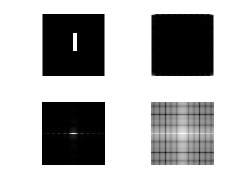

Ic = zeros(191,191);
Ic(:,:)=0;
Ic(60:115,95:105)=255;

f1 = abs(fft2(Ic));
f2 = abs(fftshift(fft2(Ic)));
f3 = im2uint8(mat2gray(log(double(abs(f2)+0.003))));

figure
subplot(2,2,1)
imshow(Ic)
subplot(2,2,2)
imshow(f1,[])
subplot(2,2,3)
imshow(f2,[])
subplot(2,2,4)
imshow(f3)

2 Reproduzca los resultados de la siguiente figura, que muestra las propiedades de traslación y rotación de la transformada de fourier.

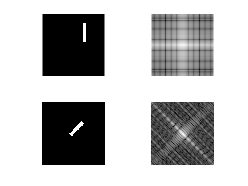

Ic2 = im2uint8(zeros(191,191));
Ic2(30:85,125:135)=255;

f1 = abs(fftshift(fft2(Ic2)));
f2 = im2uint8(mat2gray(log(double(abs(f1)+0.003))));

Ic3 = zeros(191,191);
Ic3(:,:)=0;
Ic3(60:115,95:105)=255;

[x, y] = size(Ic3);
tam = 2*round((x^2+y^2)^0.5)+5;
tx = tam/2 ; ty = tam/2;
theta = 315*pi/180;
seno = sin(theta);
coseno = cos(theta);

Img_Rotacion = zeros(tam, tam);
M_rotacion = [coseno seno 0; -seno coseno 0; tx ty 1];
for i=1:x
    for j=1:y
        xy = ([i j 1] * M_rotacion);
        Img_Rotacion(round(xy(1)), round(xy(2)):round(xy(2))+1) = Ic(i,j);
    end
end

a1 = 324;
a2 = 515;
b1 = 177;
b2 = 368;

Ic3 = Img_Rotacion(a1:a2,b1:b2);

f3 = abs(fftshift(fft2(Ic3)));
f4 = im2uint8(mat2gray(log(double(abs(f3)+100))));

figure
subplot(2,2,1)
imshow(Ic2)
subplot(2,2,2)
imshow(f2)
subplot(2,2,3)
imshow(Ic3)
subplot(2,2,4)
imshow(f4)

3 Reproduzca los resultados de la siguiente figura.

clc;
clear;
close all;

Img = double(imread("FigP0402(a)(woman).tif"));
fft = fft2(Img);
sfft = fftshift(fft);

prueba = ifft2(sfft);
angulofase = angle(sfft);

I_fft_recon = abs(fft)*exp(1j*angulofase);
I_recon = ifft(I_fft_recon);

% [M, N] = size(fft);
% fourier=double(zeros(M,N));
    
% for u=0:M-1
%     for v=0:N-1
%         mat = double(zeros(M,N));
%         for x=0:M-1
%             for y=0:N-1
%                  mat(x+1,y+1) = (1/(M*N))*fft(x+1,y+1)*exp(1j*angulofase(x+1,y+1));
%             end
%         end 
%         fourier(u+1,v+1) = sum(sum(mat));
%     end
% end


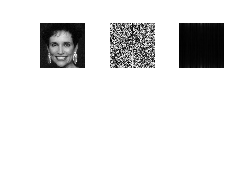

% figure 
% imshow(fourier,[])

figure
subplot(2,3,1)
imshow(Img,[]);
subplot(2,3,2)
imshow(angulofase,[]);
subplot(2,3,3)
imshow(abs(I_recon),[]);
subplot(2,3,4)
imshow(log(abs(sfft)));

% subplot(2,3,5)
% 
% subplot(2,3,6)

4. cree las funciones fft2 y ifft2

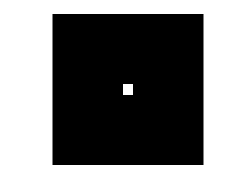

Img = zeros(15,15);
Img(8,8)=255;

figure
imshow(Img)


f1 = fft2(Img);

figure
subplot(1,2,1)
imshow(f1,[]);title("fft2 Matlab");

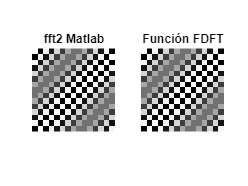

fourier=FDFT(Img);
subplot(1,2,2)
imshow(fourier,[]);title("Función FDFT");

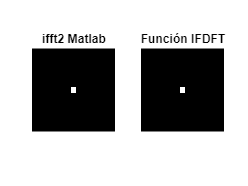

Img = zeros(15,15);
Img(8,8)=255;
Img = fft2(Img);

figure
f1 = ifft2(Img);
subplot(1,2,1)
imshow(f1,[]);title("ifft2 Matlab");
subplot(1,2,2)
ifourier=IFDFT(Img);
imshow(ifourier,[]);title("Función IFDFT");

5. hacer una funcion de filtros

a)

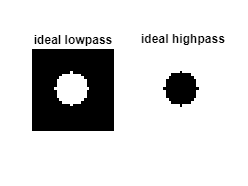

clc;
clear;
close all;

figure;
subplot(1,2,1)
Hideal1 = filtros(30,"ideal",6,"baja",1);
imshow(Hideal1);title("ideal lowpass");
subplot(1,2,2)
Hideal2 = filtros(30,"ideal",6,"alta",1);
imshow(Hideal2);title("ideal highpass");

b)

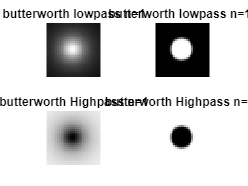

figure
subplot(2,2,1)
Hgaussian1 = filtros(30,"butter",6,"baja",1);
imshow(Hgaussian1);title("butterworth lowpass n=1");
subplot(2,2,2)
Hgaussian2 = filtros(30,"butter",6,"baja",10);
imshow(Hgaussian2);title("butterworth lowpass n=10");
subplot(2,2,3)
Hgaussian3 = filtros(30,"butter",6,"alta",1);
imshow(Hgaussian3);title("butterworth Highpass n=1");
subplot(2,2,4)
Hgaussian4 = filtros(30,"butter",6,"alta",10);
imshow(Hgaussian4);title("butterworth Highpass n=10");

c)

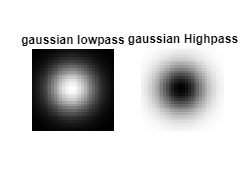

figure
subplot(1,2,1)
Hbutter1 = filtros(30,"gaussian",6,"baja",1);
imshow(Hbutter1);title("gaussian lowpass");
subplot(1,2,2)
Hbutter2 = filtros(30,"gaussian",6,"alta",1);
imshow(Hbutter2);title("gaussian Highpass");

6. 

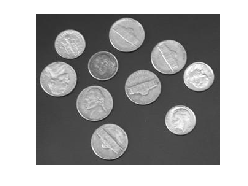

I = double(imread("coins.jpg"));

figure
imshow(I/255)

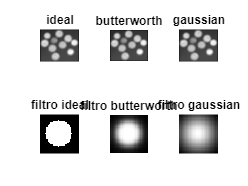


filtro1 = filtros(30,"ideal",10,"alto",1);
filtro2 = filtros(30,"butter",10,"alto",3);
filtro3 = filtros(30,"gaussian",10,"alto",1);

imgfiltrada1 = filter2(filtro1, I);
imgfiltrada2 = filter2(filtro2, I);
imgfiltrada3 = filter2(filtro3, I);

figure
subplot(2,3,1)
imshow(imgfiltrada1,[]);title("ideal");
subplot(2,3,2)
imshow(imgfiltrada1,[]);title("butterworth");
subplot(2,3,3)
imshow(imgfiltrada1,[]);title("gaussian");
subplot(2,3,4)
imshow(filtro1,[]);title("filtro ideal");
subplot(2,3,5)
imshow(filtro2,[]);title("filtro butterworth");
subplot(2,3,6)
imshow(filtro3,[]);title("filtro gaussian");